# Plant

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.

plantPath = strcat(commonPath,'\Plant Model\');
latestPlant = latestTimeParse(plantPath,'plant');
load(latestPlant)
clear plantPath latestPlant

# Input Signals1

inputPath = strcat(commonPath,'\Performance Input Signals\');
latestSlow = latestTimeParse(inputPath,'performanceInputsSlow');
latestFast = latestTimeParse(inputPath,'performanceInputsFast');
latestPureSin = latestTimeParse(inputPath,'pureSin');
load(latestSlow)
load(latestFast)
clear inputPath latestSlow latestFast
load(latestPureSin)
clear inputPath latestSlow latestFast latestPureSin

# Globals

delta_t = t(2)-t(1);
delta_pureSinTime = pureSinTime(2)-pureSinTime(1);
KpStatic = 1;
KiStatic = 10;
tdStatic=0.04;

# Toggles

togRMSFreq = 0;
togSinglePoint = 1;
figurePath = strcat(commonPath,'\Golden Figures');

# Model

%Model Setup
tend = num2str(pureSinTime(end));
stepsize = num2str(delta_pureSinTime);
simName = 'HybridSaccadeFF';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize,'FastRestart','on') %'SimulationMode','accelerator','SimCompilerOptimization','on'
save_system(simName)

# Single Point Hybrid / Smooth comparison

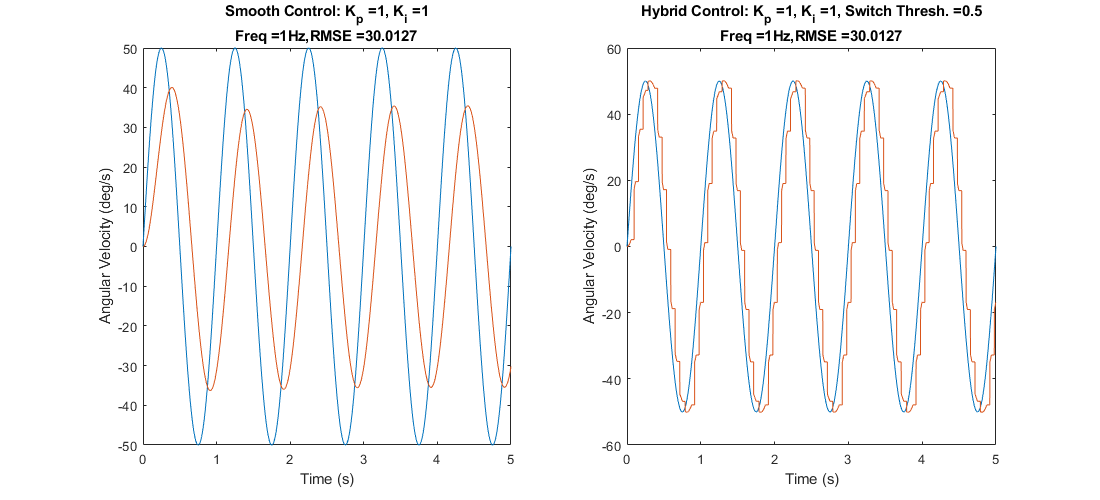

smoothOut10 =          0    0.0001    0.0003    0.0006    0.0011    0.0017    0.0024    0.0033    0.0043    0.0054    0.0067    0.0081    0.0096    0.0113    0.0131    0.0150    0.0171    0.0193    0.0216    0.0241    0.0267    0.0295    0.0324    0.0354    0.0385    0.0418    0.0452    0.0488    0.0525    0.0563    0.0603    0.0644    0.0687    0.0731    0.0776    0.0822    0.0870    0.0920    0.0970    0.1022    0.1076    0.1131    0.1187    0.1244    0.1303    0.1364    0.1425    0.1488    0.1553    0.1618
         0    0.0001    0.0005    0.0012    0.0021    0.0033    0.0048    0.0065    0.0085    0.0108    0.0133    0.0161    0.0192    0.0225    0.0261    0.0300    0.0342    0.0386    0.0433    0.0482    0.0534    0.0589    0.0647    0.0707    0.0771    0.0836    0.0905    0.0976    0.1050    0.1127    0.1206    0.1288    0.1373    0.1461    0.1551    0.1644    0.1740    0.1839    0.1940    0.2045    0.2151    0.2261    0.2373    0.2489    0.2606    0.2727    0.2850    0.2976    0

hybridOut10 =          0    0.0001    0.0003    0.0006    0.0011    0.0017    0.0024    0.0033    0.0043    0.0054    0.0067    0.0081    0.0096    0.0113    0.0131    0.0150    0.0171    0.0193    0.0216    0.0241    0.0267    0.0295    0.0324    0.0354    0.0385    0.0418    0.0452    0.0488    0.0525    0.0563    0.0603    0.0644    0.0687    0.0731    0.0776    0.0822    0.0870    0.0920    0.0970    0.1022    0.1076    0.1131    0.1187    0.1244    0.1303    0.1364    0.1425    0.1488    0.1553    0.1618
         0    0.0001    0.0005    0.0012    0.0021    0.0033    0.0048    0.0065    0.0085    0.0108    0.0133    0.0161    0.0192    0.0225    0.0261    0.0300    0.0342    0.0386    0.0433    0.0482    0.0534    0.0589    0.0647    0.0707    0.0771    0.0836    0.0905    0.0976    0.1050    0.1127    0.1206    0.1288    0.1373    0.1461    0.1551    0.1644    0.1740    0.1839    0.1940    0.2044    0.2151    0.2261    0.2373    0.2488    0.2606    0.2727    0.2850    0.2976    0

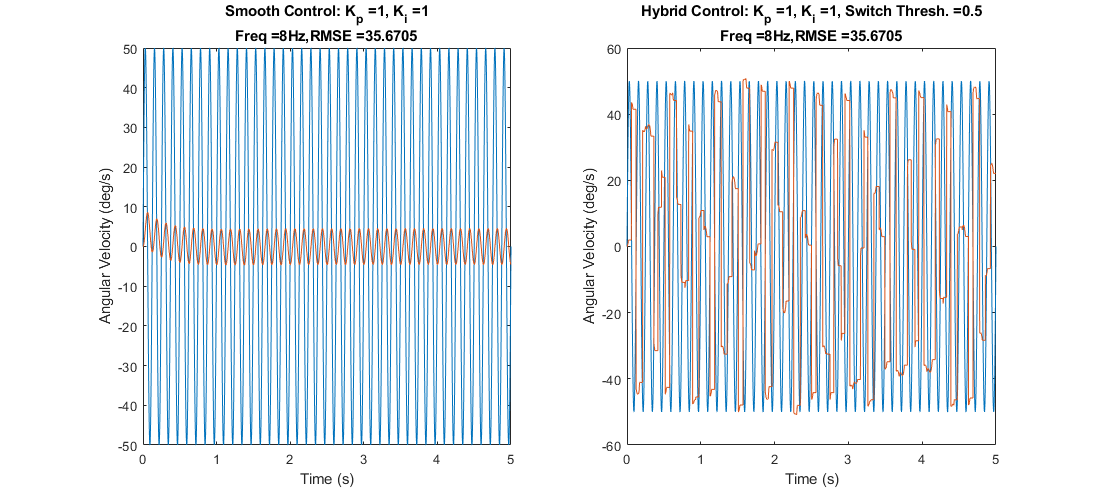

smoothOut80 =          0    0.0001    0.0003    0.0006    0.0011    0.0017    0.0024    0.0033    0.0043    0.0054    0.0067    0.0081    0.0096    0.0113    0.0131    0.0150    0.0171    0.0193    0.0216    0.0241    0.0267    0.0295    0.0324    0.0354    0.0385    0.0418    0.0452    0.0488    0.0525    0.0563    0.0603    0.0644    0.0687    0.0731    0.0776    0.0822    0.0870    0.0920    0.0970    0.1022    0.1076    0.1131    0.1187    0.1244    0.1303    0.1364    0.1425    0.1488    0.1553    0.1618
         0    0.0001    0.0005    0.0012    0.0021    0.0033    0.0048    0.0065    0.0085    0.0108    0.0133    0.0161    0.0192    0.0225    0.0261    0.0300    0.0342    0.0386    0.0433    0.0482    0.0534    0.0589    0.0647    0.0707    0.0771    0.0836    0.0905    0.0976    0.1050    0.1127    0.1206    0.1288    0.1373    0.1461    0.1551    0.1644    0.1740    0.1839    0.1940    0.2045    0.2151    0.2261    0.2373    0.2489    0.2606    0.2727    0.2850    0.2976    0

hybridOut80 =          0    0.0001    0.0003    0.0006    0.0011    0.0017    0.0024    0.0033    0.0043    0.0054    0.0067    0.0081    0.0096    0.0113    0.0131    0.0150    0.0171    0.0193    0.0216    0.0241    0.0267    0.0295    0.0324    0.0354    0.0385    0.0418    0.0452    0.0488    0.0525    0.0563    0.0603    0.0644    0.0687    0.0731    0.0776    0.0822    0.0870    0.0920    0.0970    0.1022    0.1076    0.1131    0.1187    0.1244    0.1303    0.1364    0.1425    0.1488    0.1553    0.1618
         0    0.0001    0.0005    0.0012    0.0021    0.0033    0.0048    0.0065    0.0085    0.0108    0.0133    0.0161    0.0192    0.0225    0.0261    0.0300    0.0342    0.0386    0.0433    0.0482    0.0534    0.0589    0.0647    0.0707    0.0771    0.0836    0.0905    0.0976    0.1050    0.1127    0.1206    0.1288    0.1373    0.1461    0.1551    0.1644    0.1740    0.1839    0.1940    0.2044    0.2151    0.2261    0.2373    0.2488    0.2606    0.2727    0.2850    0.2976    0

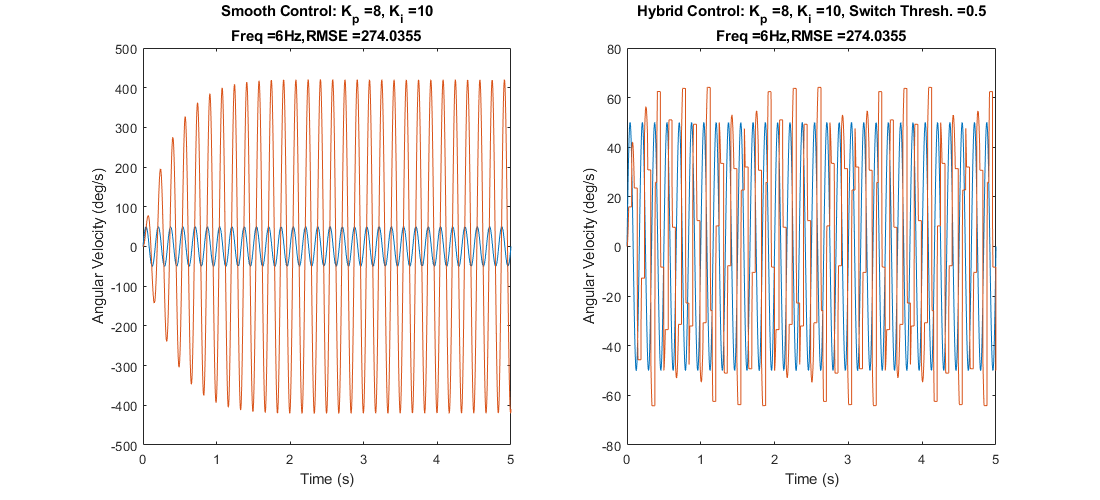

smoothOut60 =          0    0.0005    0.0021    0.0048    0.0086    0.0134    0.0192    0.0261    0.0340    0.0431    0.0532    0.0644    0.0767    0.0901    0.1045    0.1201    0.1368    0.1546    0.1735    0.1934    0.2144    0.2364    0.2596    0.2838    0.3090    0.3354    0.3628    0.3913    0.4209    0.4516    0.4834    0.5164    0.5505    0.5857    0.6220    0.6595    0.6981    0.7379    0.7787    0.8207    0.8637    0.9078    0.9530    0.9992    1.0464    1.0945    1.1436    1.1936    1.2445    1.2962
         0    0.0011    0.0043    0.0097    0.0171    0.0267    0.0384    0.0522    0.0681    0.0861    0.1063    0.1287    0.1533    0.1801    0.2091    0.2403    0.2737    0.3092    0.3469    0.3868    0.4287    0.4729    0.5191    0.5675    0.6180    0.6707    0.7255    0.7825    0.8417    0.9032    0.9668    1.0327    1.1008    1.1713    1.2439    1.3189    1.3961    1.4755    1.5572    1.6411    1.7272    1.8154    1.9056    1.9980    2.0923    2.1886    2.2867    2.3867    2

hybridOut60 =          0    0.0005    0.0021    0.0048    0.0085    0.0133    0.0192    0.0261    0.0341    0.0432    0.0533    0.0645    0.0768    0.0902    0.1047    0.1202    0.1368    0.1545    0.1733    0.1932    0.2141    0.2362    0.2593    0.2835    0.3088    0.3352    0.3627    0.3913    0.4210    0.4518    0.4837    0.5167    0.5508    0.5860    0.6224    0.6598    0.6983    0.7379    0.7787    0.8205    0.8635    0.9076    0.9527    0.9989    1.0461    1.0943    1.1435    1.1935    1.2444    1.2961
         0    0.0011    0.0043    0.0096    0.0170    0.0266    0.0383    0.0522    0.0682    0.0863    0.1066    0.1291    0.1537    0.1804    0.2093    0.2404    0.2736    0.3090    0.3466    0.3863    0.4282    0.4723    0.5186    0.5670    0.6176    0.6704    0.7254    0.7826    0.8420    0.9036    0.9674    1.0334    1.1016    1.1720    1.2446    1.3194    1.3964    1.4757    1.5571    1.6408    1.7267    1.8148    1.9051    1.9975    2.0919    2.1882    2.2864    2.3864    2

Unrecognized function or variable 'x'.

Error in sineFit (line 6)
    zx = x(yz .* circshift(yz,[0 1]) <= 0);     % Find zero-crossings

if togSinglePoint == 1
    
   freqindex = 10;
   Kp = 1;
   Ki = 1;
   td =tdStatic;
   switchThresh = 0.5;
   T_lim_up = inf;
   T_lim_low = -inf;
   [smoothOut10, hybridOut10] = singlePointCompare(Kp,Ki,td,switchThresh,freqindex,sinfreqs,pureSinTime,pureSin,...
       G_plant,T_lim_up,T_lim_low,simName);
%    savePath =strcat(figurePath,'\SinglePointHybrid\lowgainlowfreq')
%    export_fig (savePath,'-eps')
    
    freqindex = 80;
    [smoothOut80, hybridOut80] = singlePointCompare(Kp,Ki,td,switchThresh,freqindex,sinfreqs,pureSinTime,pureSin,...
       G_plant,T_lim_up,T_lim_low,simName);
%    savePath =strcat(figurePath,'\SinglePointHybrid\lowgainhighfreq')
%    export_fig (savePath,'-eps')
    
    freqindex = 60;
    Kp = 8;
    Ki = 10;
    [smoothOut60, hybridOut60] = singlePointCompare(Kp,Ki,td,switchThresh,freqindex,sinfreqs,pureSinTime,pureSin,...
       G_plant,T_lim_up,T_lim_low,simName);
%    savePath =strcat(figurePath,'\SinglePointHybrid\highgainmedfreq')
%    export_fig (savePath,'-eps')
    
    sineFit(hybridOut60(freqindex,:),pureSineTime)
end

# RMSE as a function of frequency and switching threshold

if togRMSFreq == 1  
    %First, the smooth system using lsim
    Kp = 3:1:10;
    for j = 1:length(Kp)
        Ki = KiStatic;
        td =tdStatic;
        [~,smoothRMSE] = simRMSE(Kp(j),Ki,td,0,0,G_plant,pureSin,pureSinTime,sinfreqs,[],'');
        
        %Next, Hybrid System with Infinite switching threshold (should match
        %pure smooth system)
        tLimSet = struct('T_lim_up',inf,'T_lim_low',-inf);
        [~,hybridInfRMSE] = simRMSE(Kp(j),Ki,td,inf,1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);
        %Animation
        basepath = strcat(commonPath,'\Hybrid Performance Results');
        fig=figure('Position', [100, 100, 1024, 1200]);
        clear F
        switchThreshRange = 0:0.2:10;
        for i = 1:length(switchThreshRange)
            tic
            [~,hybridTempRMSE] = simRMSE(Kp(j),Ki,td,switchThreshRange(i),1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);  
            plot(sinfreqs,smoothRMSE,'k',sinfreqs,hybridInfRMSE,'.r',sinfreqs,hybridTempRMSE,'b')
            title(sprintf('K_p = %.1f, K_i = %.1f, Switch Threshold = %.1f',Kp(j),Ki,switchThreshRange(i)))
            legend('Smooth Lsim','Smooth Simulink','Hybrid')
            F(i) = getframe(fig);
            toc
        end
        v = VideoWriter(strcat(basepath,'\rmseFreqSwitchVideo_Kp_',num2str(Kp(j)),'_Ki_',num2str(Ki),'.avi'));
        v.FrameRate = 2;
        open(v)
        writeVideo(v,F);
        close(v)  
    end
    
        Ki = 1:1:10;
    for j = 1:length(Ki)
        Kp = KpStatic;
        td =tdStatic;
        [~,smoothRMSE] = simRMSE(Kp,Ki(j),td,0,0,G_plant,pureSin,pureSinTime,sinfreqs,[],'');
        
        %Next, Hybrid System with Infinite switching threshold (should match
        %pure smooth system)
        tLimSet = struct('T_lim_up',inf,'T_lim_low',-inf);
        [~,hybridInfRMSE] = simRMSE(Kp,Ki(j),td,inf,1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);
        %Animation
        basepath = strcat(commonPath,'\Hybrid Performance Results');
        fig=figure('Position', [100, 100, 1024, 1200]);
        clear F
        switchThreshRange = 0:0.2:10;
        for i = 1:length(switchThreshRange)
            tic
            [~,hybridTempRMSE] = simRMSE(Kp,Ki(j),td,switchThreshRange(i),1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);  
            plot(sinfreqs,smoothRMSE,'k',sinfreqs,hybridInfRMSE,'.r',sinfreqs,hybridTempRMSE,'b')
            title(sprintf('K_p = %.1f, K_i = %.1f, Switch Threshold = %.1f',Kp,Ki(j),switchThreshRange(i)))
            legend('Smooth Lsim','Smooth Simulink','Hybrid')
            F(i) = getframe(fig);
            toc
        end
        v = VideoWriter(strcat(basepath,'\rmseFreqSwitchVideo_Kp_',num2str(Kp),'_Ki_',num2str(Ki(j)),'.avi'));
        v.FrameRate = 2;
        open(v)
        writeVideo(v,F);
        close(v)  
    end
end

# Sweep across switching threshold

%Input
fin = 50;
V_in = [pureSinTime' pureSin(fin,:)'];

%Parameters
sac_time = 0.04; %Saccade completion "delay"
n_delay = .04; %Neurological Delay
T_lim_up = inf; %Biological Torque Limit upper
T_lim_low = -inf; %Biological Torque Limit upper
K_P = 5; %Proportional Gain
K_I = 10; %Integral Gain of smooth system


switch_threshbig = 0:0.1:5; %Integrated error threshold for switching between smooth/saccadic
rmse = zeros(1,length(switch_threshbig));
for i = 1:size(switch_threshbig,2)
    switch_thresh = switch_threshbig(i);
    out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');
    rmse(i) = sqrt(mean((out.V_out-V_in(:,2)).^2));
end

figure
plot(switch_threshbig,rmse)

ylabel('RMSE')
xlabel('Switching Threshold')
title(strcat('K_p =',num2str(K_P),', K_i = ',num2str(K_I),', f_{in} = ',num2str(sinfreqs(fin)),' Hz'))


# Optimal Point Gain Sweep

Prange = 1:1:15;
Irange = 1:1:15;
switchrange = 0.5:0.5:10;
freqrange = 1:1:5;
estimatedTimeHrs = (.035*numel(Prange)*numel(Irange)*numel(switchrange)*numel(freqrange))/3600
estimatedTimeMins = (.035*numel(Prange)*numel(Irange)*numel(switchrange)*numel(freqrange))/60
estimatedTimeSecs = (.035*numel(Prange)*numel(Irange)*numel(switchrange)*numel(freqrange))/1

%Parameters
sac_time = 0.04; %Saccade completion "delay"
n_delay = .04; %Neurological Delay
T_lim_up = inf; %Biological Torque Limit upper
T_lim_low = -inf; %Biological Torque Limit upper

%Input
%V_in = [t' sos'];

% %Parallel Simulation Setup
% tic
% numSims = size(switchrange,2)*size(Prange,2)*size(Irange,2);
% clear simIn
% simIn(1:numSims) = Simulink.SimulationInput(simName);
% 
% iter = 1;
% for i = 1:size(Prange,2)
%     for j = 1:size(Irange,2)
%         for k = 1:size(switchrange,2) 
%             %Constants
%             simIn(iter) = simIn(iter).setVariable('sac_time',sac_time,'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('n_delay',n_delay,'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('T_lim_up',T_lim_up,'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('T_lim_low',T_lim_low,'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('G_plant',G_plant,'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('V_in',V_in,'Workspace',simName);
%             
%             %Variables
%             simIn(iter) = simIn(iter).setVariable('switch_thresh',switchrange(k),'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('K_P',Prange(i),'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('K_I',Irange(j),'Workspace',simName);
%             
%             iter = iter + 1;
%         end
%         
%     end
% end
% out = parsim(simIn,'UseFastRestart','on');
% toc

tic
minswitch = zeros(size(freqrange,2),size(Prange,2)*size(Irange,2),3);
error = zeros(1,size(switchrange,2));
iter=1;
for l = 1:size(freqrange,2)
   puresine = 50*sin(2*pi*freqrange(l)*t);
   V_in = [t' puresine'];
   for i = 1:size(Prange,2)
    for j = 1:size(Irange,2)
        K_P = Prange(i);
        K_I = Irange(j);

        for k = 1:size(switchrange,2)
            switch_thresh = switchrange(k);
            out = sim('HybridSaccadeFF.slx');
            error(k) = sum(abs(sos'-out.V_out));
        end
        
        [minerror,index] = min(error);
        minswitch(l,iter,:) = [K_P K_I switchrange(index)];
        iter=iter+1;
    end  
    end 
end

toc

filename1 = strcat('ch','_',num2str(scale),'_',num2str(f_start),'_',num2str(f_end),'_');
filename2 = strcat('ssf','_',num2str(f(1)),'_',num2str(f(2)),'_',num2str(f(3)),'_');
filename3 = strcat('ssp','_',num2str(p(1)),'_',num2str(p(2)),'_',num2str(p(3)),'_');
filename4 = strcat('kp','_',num2str(Prange(1)),'_',num2str(Prange(2)-Prange(1)),'_',num2str(Prange(end)),'_');
filename5 = strcat('ki','_',num2str(Irange(1)),'_',num2str(Irange(2)-Irange(1)),'_',num2str(Irange(end)),'_');
filename6 = strcat('sw','_',num2str(switchrange(1)),'_',num2str(switchrange(2)-switchrange(1)),'_',num2str(switchrange(end)));
filename7 = strcat('sw','_',num2str(freqrange(1)),'_',num2str(freqrange(2)-freqrange(1)),'_',num2str(freqrange(end)));
filename = strcat(filename1,filename2,filename3,filename4,filename5,filename6,'.mat')
save(filename,'minswitch','chirps','sos','scale')


for i = 1:size(freqrange,2)
    figure('Renderer', 'painters', 'Position', [10 10 1000 700])
    set(gcf, 'Color', 'w');
    sf = fit([minswitch(i,:,1)', minswitch(i,:,2)'],minswitch(i,:,3)','cubicinterp');
    plot(sf)
end




ax = gca;
ax.XAxis.FontSize = 12;
ax.XAxis.FontName = 'Segoe UI';
ax.YAxis.FontSize = 12;
ax.YAxis.FontName = 'Segoe UI';
ax.ZAxis.FontSize = 12;
ax.ZAxis.FontName = 'Segoe UI';
xlabel('K_P','FontName','Segoe UI Semibold','FontSize',14)
ylabel('K_I','FontName','Segoe UI Semibold','FontSize',14)
zlabel('Optimum Switching Threshold','FontName','Segoe UI Semibold','FontSize',14)
box on
view(-30,25)
